# GReS - Understanding the Mesh

## Introduction

This tutorial introduces you to the basic GReS features to input a mesh, visualize it and manage the output of a simple simulation. 

cd(fullfile(gres_root,'Tutorial','grid'))

## VTK file format

GReS supports two mesh file formats, `.vtk and .msh.` In this example, you will see how to read a mesh representing a simple cube. The [VTK](https://vtk.org/doc/nightly/html/index.html) (Visualization ToolKit) format is a widely used format for storing mesh and scientific data. It supports both ASCII and binary encoding and can represent structured and unstructured meshes. It is especially well-suited for visualization with tools such as ParaView or VisIt. The `.vtk` files can include point coordinates, connectivity (cells), cell types, and optional scalar or vector data for post-processing or visualization. Here is an example of a simple VTK file [Box.vtk](matlab:open('./Mesh\Box.vtk')).

**HEADER**

The file begins with a standard VTK header:

**In the current version of the code, this is the only admitted header for a vtk file. If you try to input a file where the above informations are different, GReS will throw an error.**

**POINTS**

This section lists 8 vertices deifning the corners of the cube, each with x, y, z coordinates:

**CELLS**

There are 3 cells:

The first two are quadrilaterals (4-node faces).

The third is a hexahedron (8-node volume).

The second number, 19, is the total number of integers appearing in the section:

3 cell definitions: (1×5) + (1×5) + (1×9) = 19 integers

**CELL_TYPES** 

This section characterizes each cell with an integer corresponding to the shape.

9 = quadrilateral (used for surfaces)

12 = hexahedron (used for the volume)

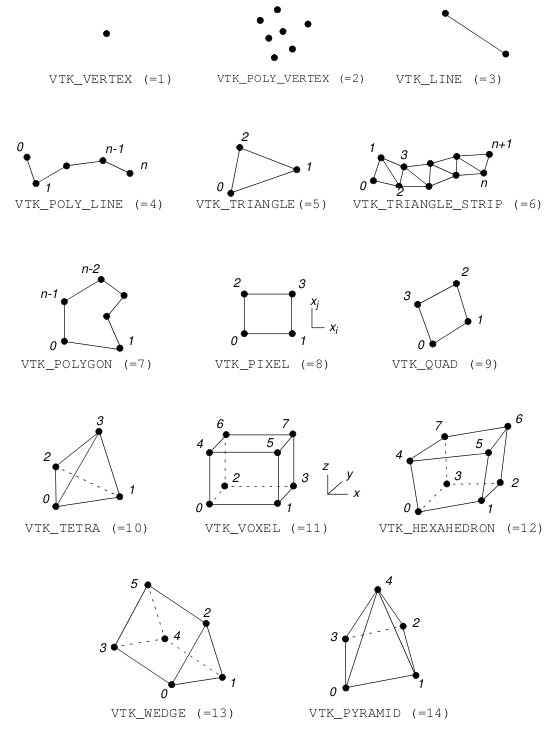

**CELL_DATA**

This scalar field assigns an ID to each cell.

The top and bottom faces have different IDs (1 and 2). The volume has ID 1.

These IDs are very useful to identify different regions of the grid where to impose boundary condition. 

## MSH file format

The .msh format is the native format of [GMSH](https://gmsh.info/doc/texinfo/gmsh.html), a powerful and open-source mesh generator. For the unit cube shown before, this is what the input file looks like.

**GReS only supports .msh file of version 2.2, which is not the latest one. **

We refer the user to the Gmsh tutorial for a detailed description of the .msh file format and how to use it for generating a grid. Note that the `.msh` file supports name for the cell or surface region under the `$PhysicalNames` section

## Reading a mesh in GReS

To read a mesh, you first need to create a `Mesh` object.

grid = Grid();

If we print the object

grid

grid =   Grid with properties:

           nDim: 0
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 0
    coordinates: []


we see that this object contain numerous properties still to be defined. 

To populate this properties, call the `importMesh() `method with the name of the mesh file.

grid.importMesh('Mesh/Box.vtk');

The file name must have either '.vtk' or '.msh' extension, so that GReS knows how to read the file. The path to the file is always relative to the location of the main file.

*Under the hood, GReS is using compiled C++ *[*mex function*](https://www.mathworks.com/help/matlab/call-mex-file-functions.html)* to read the grid. Take a look at the Setup tutorial to see how to compile c++ code and produce mex files before starting using it.*

Now print again the msh object

grid

grid =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 8
    coordinates: [8×3 double]


The mesh is a 3D mesh (`nDim=3`) with 8 nodes, 1 cell and 2 surfaces. Notice the difference between the 6 geometrical surfaces of the cube and the 2 physical surfaces defined in Box.vtk.

% structure for cell informations
grid.cells

ans = struct with fields:
        connectivity: [1 2 3 4 5 6 7 8]
                 num: 1
              volume: 1.0000
              center: [0.5000 0.5000 0.5000]
             VTKType: 12
                 tag: 1
                nTag: 1
            numVerts: 8
         cells2faces: [1×1 ArrayOfArrays]
    cells2localFaces: [1×1 ArrayOfArrays]
            vtkTypes: 12


% structure for surfaces
grid.surfaces

ans = struct with fields:
    connectivity: [2×4 double]
             num: 2
            area: [2×1 double]
        numVerts: [2×1 double]
         VTKType: [2×1 double]
             tag: [2×1 double]
            nTag: 2
          center: [2×3 double]
          normal: [2×3 double]
          faceId: [2×1 double]
        vtkTypes: 9


% structure for faces
grid.faces

ans = struct with fields:
             num: 6
        numVerts: [6×1 double]
            area: [6×1 double]
          normal: [6×3 double]
          center: [6×3 double]
       neighbors: [6×2 double]
      isBoundary: [6×1 logical]
    connectivity: [1×1 ArrayOfArrays]


Note the difference between surfaces and faces in GReS. `faces` store informations for all internal faces in the grid. `surfaces` is the subset of tagged faces in the boundary of a domain, where boundary conditions or domain coupling conditions are enforced. The `surfaces.faceId `property maps the surfaces to the corresponding face id. 

The information delivered by the CELL_DATA section is stored in the vectors `cellTag` and` surfaceTag`. CELL TYPE section of the vtk file is stored in the vectors `cellVTKType` and` surfaceVTKType`. 

Let's now import the .msh version of the grid and see the differences.

grid.importMesh('Mesh/Box.msh');
grid

grid =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 8
    coordinates: [8×3 double]


## A more advanced example

Let's now import a more complicated grid, the one used in the [DeepAquifer](matlab:open('../../Tests/DeepAquifer/Input/ReservoirTest_Hexa.msh')) test case. 

gridAdvanced = Grid();
gridAdvanced.importMesh('Mesh/Reservoir.msh')
gridAdvanced

gridAdvanced =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 3509
    coordinates: [3509×3 double]


Check out the workspace to inspect the properties of grid`Advanced`. This object contains many `cells.tag` and `surface.tag`.

## **Creating structured grids**

GReS provides also fast ways to generate simple structured cartesian grids, without the need of reading from external mesh files.

The command 

grid = structuredMesh(10,5,3,[0 50],[-10 40],[0 6])

grid =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 264
    coordinates: [264×3 double]


creates a cartesian mesh with 10 elements along the x-direction, 5 along the y-direction and 3 along the z-direction. The limiting coordinates of the grid are specified by the remaining 1x2 input arrays. Hence, this grid is a box going from 0 to 50 along x, from -10 to 40 along y, and from 0 to 6 along z.

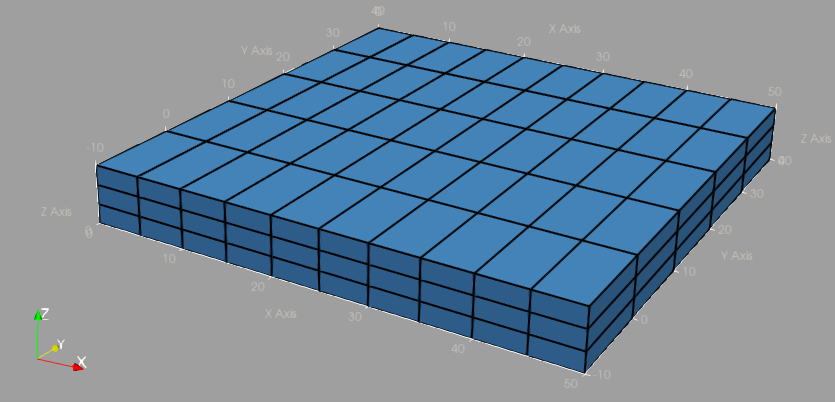

We can also create structured grids with non-uniform spacing of the nodes along the axis. We simply input 3 arrays of the coordinates of the nodes along x,y and z. 

xv = [0 5 15 20 25 27.5 30 31 32 38 43 50];
yv = [-10 0 10 20 25 30 40];
zv = [0 2 3 4 6];

grid = structuredMesh(xv,yv,zv)

grid =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 420
    coordinates: [420×3 double]


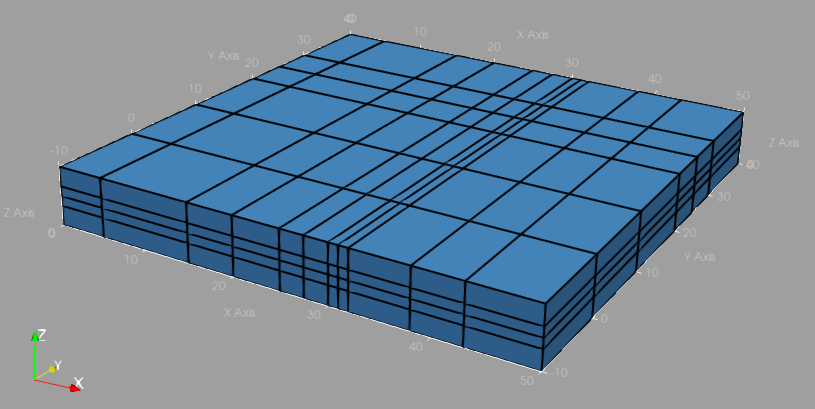

## **Creating Non-conforming structured grids**

GReS is capable of working with non-conforming grids! To create simple non-conforming grids, you can generate a BlockStructured grid made from different structured blocks of variable mesh size. Each block (indexed with classical i-j-k pattern), can be refined independently using an octree stategy. 

We first define the base grid (left figure) creating a  `BlockStructuredMesh` object.

b = BlockStructuredMesh(2,2,2,[0 1],[0 1],[0 1],3);
b.refineRecursive([1 1 1],2);
b.refineRecursive([2 2 2],3);
b.refineRecursive([2 1 2],1);

That is, a simple unit cube with 8 cells (left figure).  Compared to the standard structuredMesh, we have one additional input representing the maximum level of refinement of the base grid. 

We then use the refineRecursive method to refine the sub-blocks in position (1,1,1), (2,1,2) and (2,2,2)  specify the depth of the refinements (centre figure).

b.refineRecursive([1 1 1],2);
b.refineRecursive([2 2 2],3);
b.refineRecursive([2 1 2],1);

Finally, we further refine the the second block (2,1,1) of the already refined base block (2,1,2) (right figure).

b.refineRecursive([2 1 2],2,2)
blockStructuredMesh = b.processGeometry()

blockStructuredMesh =   Grid with properties:

           nDim: 3
          cells: [1×1 struct]
       surfaces: [1×1 struct]
          faces: [1×1 struct]
          edges: []
         nNodes: 936
    coordinates: [936×3 double]


When we are done with recursive refinement, we need to call the processGeometry() method to produce a valid GReS Mesh() object.  You can inspect the resulting grid plotting its geometry in paraview, calling 

plotMesh(blockStructuredMesh,'Mesh/blockStructuredPlot')

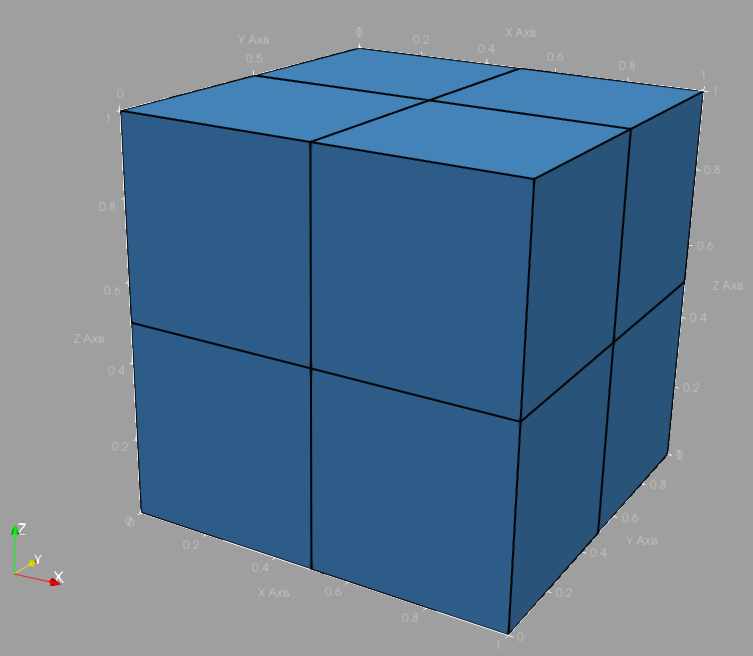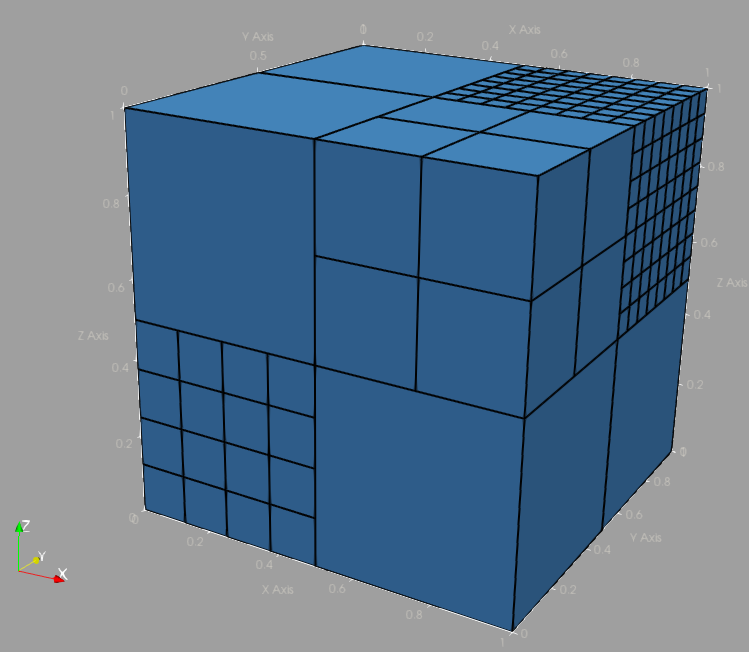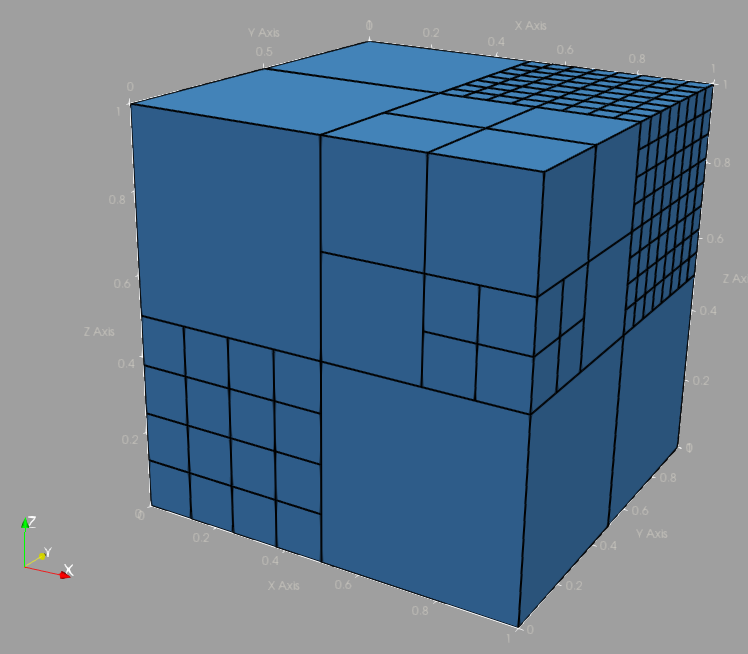

and inspecting the vtm file stores in the '*blockStructuredPlot' *output folder. 

## XML input

We can use XML input to create a Mesh using the static method Mesh.create():

help Grid.create

  create  Generate a mesh from an XML input struct or name-value pairs.
 
    GRID = create(INPUT) dispatches to the appropriate mesh constructor
    based on which field is present in INPUT:
      - 'meshFile'            : import mesh from file
      - 'StructuredMesh'      : build a uniform Cartesian hexahedral mesh
      - 'BlockStructuredMesh' : build a block-structured hexahedral mesh
 
  -------------------------------------------------------------------------
  INPUTS (name-value or struct fields)
    meshFile             - path to an existing mesh file  [string]
 
    StructuredMesh       - sub-struct with fields:
                             .NX, .NY, .NZ  number of cells along x, y, z
                             .LX, .LY, .LZ  extents [min, max]  (1x2 each)
 
    BlockStructuredMesh  - sub-struct with fields:
                             .NX, .NY, .NZ  number of cells per block
                             .LX, .LY, .LZ  extents [min, max]  